clear

data1 = readtable("DATA1.xlsx");

data2 = readtable("DATA2.xlsx");


velocidad_1 = data1(:, "VelocidadReal_m_s_");
velocidad_2 = data2(:, "VelocidadReal_m_s_");
velocidad_1 = velocidad_1{:, 1};
velocidad_2 = velocidad_2{420:840, 1};

velocidad = [velocidad_1' velocidad_2'].^3;

potencia_1 = data1(:, "PotenciaEn23kV_MW_");
potencia_2 = data2(:, "PotenciaEn23kV_MW_");
potencia_1 = potencia_1{:, 1};
potencia_2 = potencia_2{420:840, 1};
potencia = [potencia_1' potencia_2'];


for i = 3:length(velocidad)
    train_data(1, i-2) = velocidad(i-1); % u(k-1)
    train_data(2, i-2) = velocidad(i-2); % u(k-1)
    train_data(3, i-2) = potencia(i-1); %y(k-1)
    train_data(4, i-2) = potencia(i-2); %y(k-1)
end

y = potencia(3:length(potencia));

Entrenamiento red definitiva

net = fitnet(14);
net.divideParam.trainRatio = 3118/3540;
net.divideParam.valRatio= 420/3540;
net.divideParam.testRatio = 0/3540;

[net, tr] = train(net, train_data, y);

Predicciones a futuro

% Contrucción de los datos
velocidad_pred = data2(:,"VelocidadPredicha_m_s_");
potencia_test = data2(:, "PotenciaEn23kV_MW_");
velocidad_test = velocidad_pred{1:420, 1}; 
potencia_test = potencia_test{1:420, 1};

for i = 3:length(velocidad_test)
    test_data(1, i-2) = velocidad_test(i-1); % u(k-1)
    test_data(2, i-2) = velocidad_test(i-2); % u(k-1)
    test_data(3, i-2) = potencia_test(i-1); %y(k-1)
    test_data(4, i-2) = potencia_test(i-2); %y(k-1)
end

% Computing outputs
output = net(test_data);
potencia_test = potencia_test(3:420)';


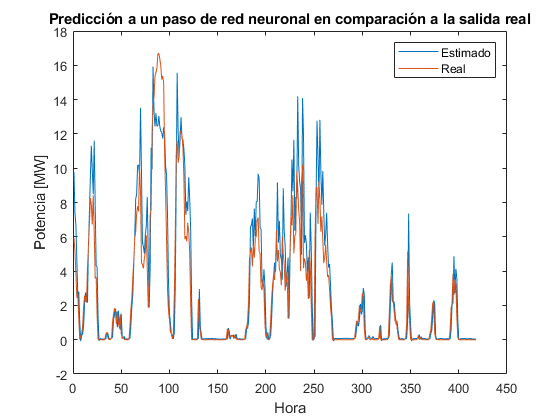


plot(output)
hold on
plot(potencia_test)
hold off

title('Predicción a un paso de red neuronal en comparación a la salida real')
xlabel('Hora')
ylabel('Potencia [MW]')
legend('Estimado', 'Real')


e = output - potencia_test;

mae_ = mae(e)

mae_ = 0.9937

RMSE = sqrt(mean(e.^2))  % Root Mean Squared Error

RMSE = 1.7035

Predicción a 12 pasos

for j=1:12
   L = length(test_data);
   test_data = test_data(:, 2:L);
   L = length(test_data);
   new_test_data = zeros(4, L);
   for i=3:L
       new_test_data(1, i-2) = test_data(1, i-1); % u(k-1)
       new_test_data(2, i-2) = test_data(2, i-2); % u(k-1)
       new_test_data(3, i-2) = output(i-1); %y(k-1)
       new_test_data(4, i-2) = output(i-2); %y(k-1)
   end
   test_data = new_test_data;
end

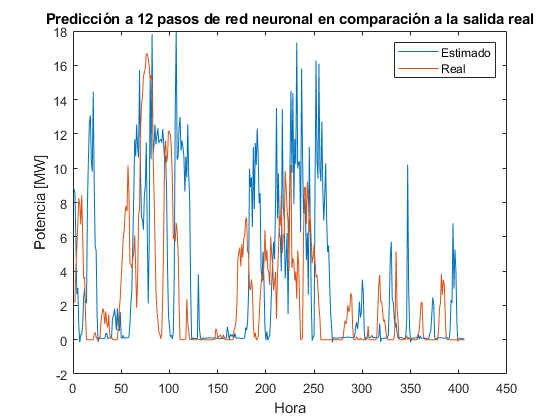

% Computing outputs
output = net(test_data);
potencia_test = potencia_test(13:418)';

plot(output)
hold on
plot(potencia_test) 
hold off

title('Predicción a 12 pasos de red neuronal en comparación a la salida real')
xlabel('Hora')
ylabel('Potencia [MW]')
legend('Estimado', 'Real')


e = output - potencia_test';

mae_ = mae(e)

mae_ = 3.4650

RMSE = sqrt(mean(e.^2))  % Root Mean Squared Error

RMSE = 5.1598

Predicción a 24 pasos

for j=1:12
   L = length(test_data);
   test_data = test_data(:, 2:L);
   L = length(test_data);
   new_test_data = zeros(4, L);
   for i=3:L
       new_test_data(1, i-2) = test_data(1, i-1); % u(k-1)
       new_test_data(2, i-2) = test_data(2, i-2); % u(k-1)
       new_test_data(3, i-2) = output(i-1); %y(k-1)
       new_test_data(4, i-2) = output(i-2); %y(k-1)
   end
   test_data = new_test_data;
end

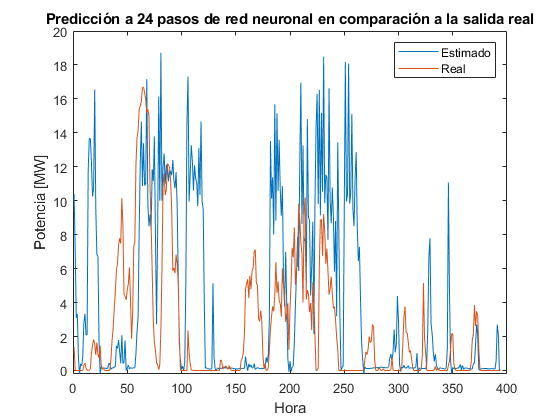

% Computing outputs
output = net(test_data);
potencia_test = potencia_test(13:406)';

plot(output)
hold on
plot(potencia_test) 
hold off

title('Predicción a 24 pasos de red neuronal en comparación a la salida real')
xlabel('Hora')
ylabel('Potencia [MW]')
legend('Estimado', 'Real')


e = output - potencia_test;

mae_ = mae(e)

mae_ = 3.5278

RMSE = sqrt(mean(e.^2))  % Root Mean Squared Error

RMSE = 5.4296